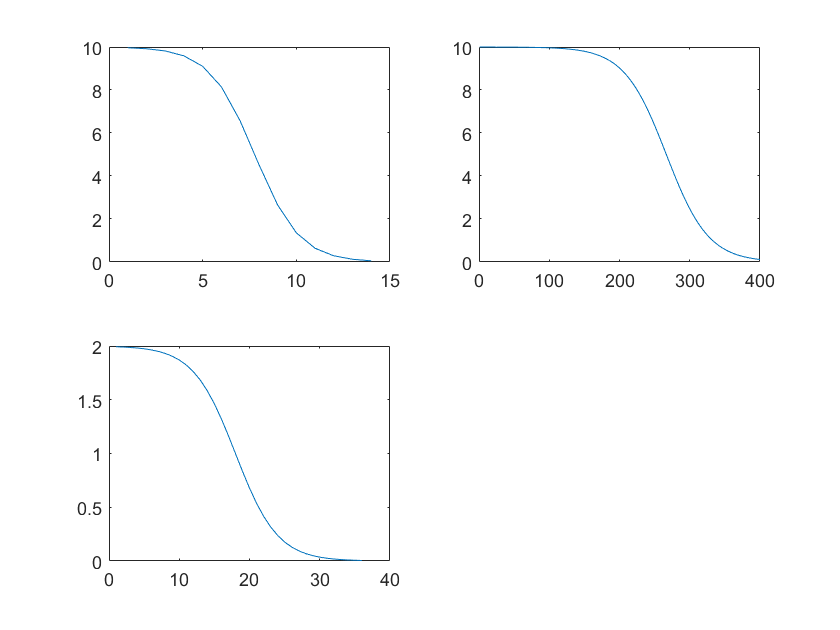


cd ..;
cd lab1\functions;
n=20;
[best,meanms,stdms,Results,BestHistory,CurrentHistory,Step]=multistartF(n,14,9,10,1.8,1.2);
[best1,meanms1,stdms1,Results1,~,~,Step1]=multistartM(n,24,11,10,1.8,1.2);
[best2,meanms2,stdms2,Results2,Step2]=jpjvsf(n);
[best3,meanms3,stdms3,Results3,Step3]=jpjvsm(n);
cd ..;cd ..;
cd lab2\functions;
[best4,Results4,meanGAesVar,stdGAesVar,BestHistory2,CurrentHistory2,Step4]...
    = GAesVarF(n,36,11,9,2,2,3);
[bestresult,Results5,meanGAesVar1,stdGAesVar1,BestHistory1,CurrentHistory1,Step5] = ...
    GAesVarM(n,38,21,14,3,2,3);


%bestresults=[best,best2,best4];

%t1={['multistartf';'jpjvsf';'GAesVarF'],[meanms;means2;meanGAesVar],[stdms;stdms2;stdG]}
% disp('for multistart fewminima: mean ');disp(meanms);disp(' std ');disp(stdms);disp(' best result ');disp(best);disp(' for multistart manyminima: mean ');disp(meanms1);disp(' std ');
% disp(stdms1);disp(' best result ');disp(best1);disp(' for 1+1 few...: mean ');disp(meanms2);disp(' std ');disp(stdms2);disp(' best result ');disp(best2);
% disp(' for 1+1 many...: mean ');disp(meanms3);disp(' std ');disp(stdms3);disp(' best result ');disp('');disp('');disp('');disp('');
% disp('');disp('');disp('');disp('');disp('');disp('');disp('');disp('');disp('');
a=[Results;Results2;Results4];
b=[Results1;Results3;Results5];

figure(1);
subplot(2,2,1);
plot(Step);
subplot(2,2,2);
plot(Step2);
subplot(2,2,3);
plot(Step4);

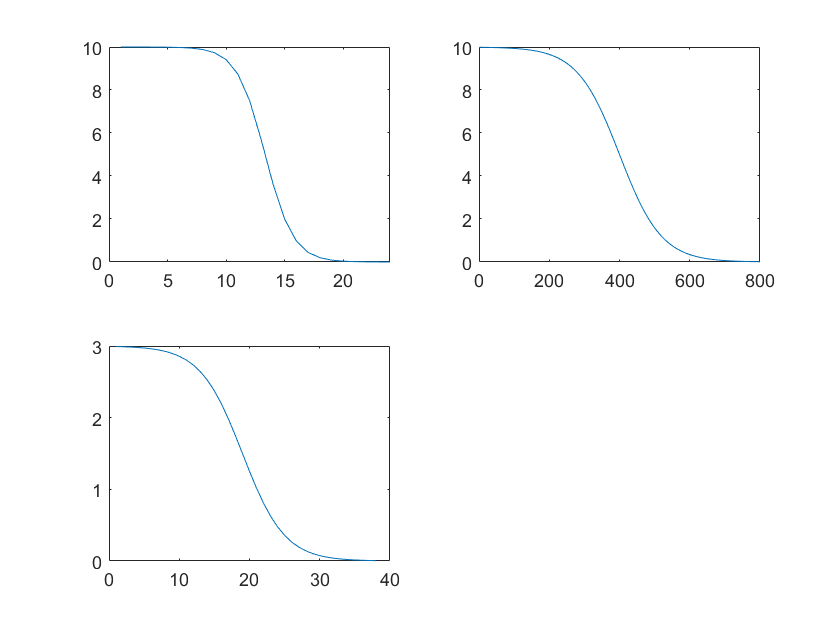


figure(2);
subplot(2,2,1);
plot(Step1);
subplot(2,2,2);
plot(Step3);
subplot(2,2,3);
plot(Step5);

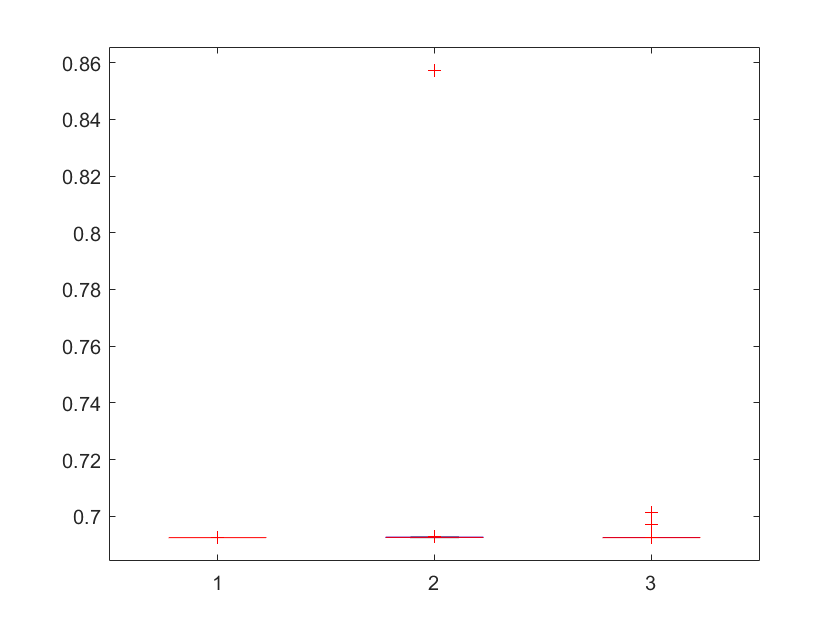

figure(3);
boxplot(a');

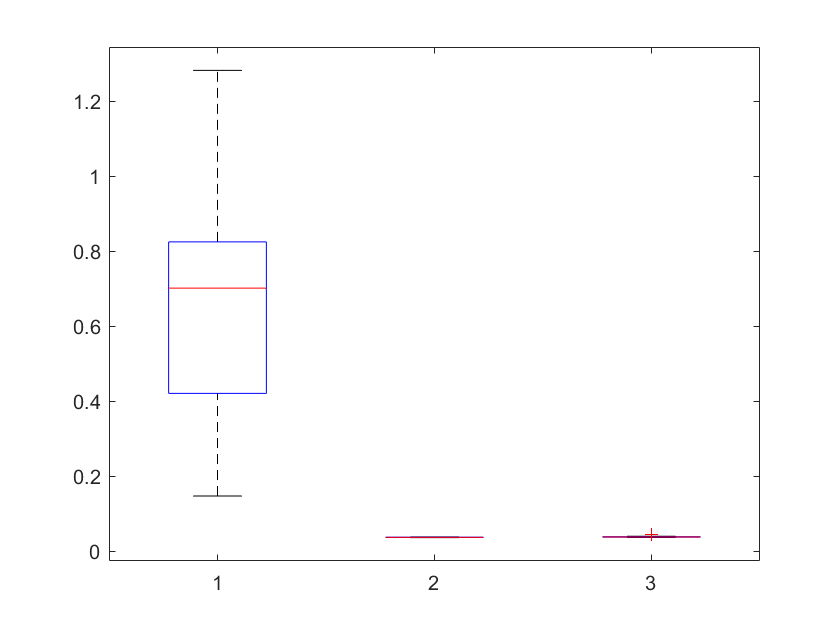

figure(4);
boxplot(b');